clear all
clc
close all

experiment = loadExp;

cd /home/ben/lampllab/Ben/Data/Awake_AP2.5_ML4.0_A1/FVB/240322/

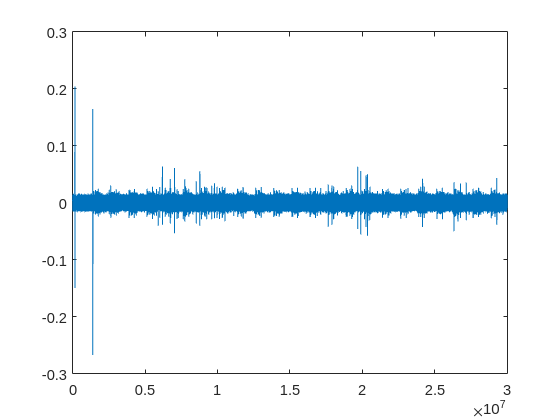

figure; plot(data(1:10000000))

ephysSound = experiment.sound.full;

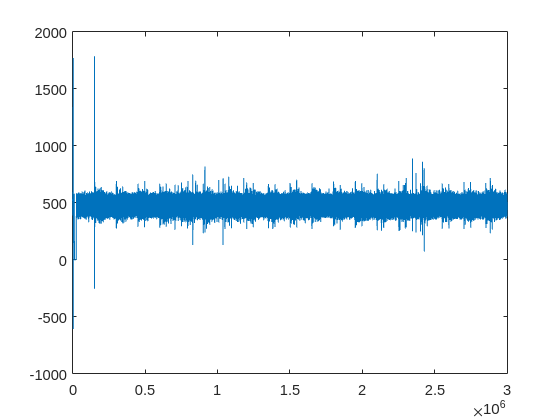

figure; plot(ephysSound(1:3000000))

experiment.timeStamp.ephys = [3768 70376764]

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [17408×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-4.2520e-06 -4.3195e-06 -4.3873e-06 -4.4552e-06 -4.5233e-06 -4.5916e-06 -4.6600e-06 -4.7285e-06 -4.7970e-06 -4.8655e-06 -4.9339e-06 -5.0023e-06 -5.0705e-06 -5.1386e-06 -5.2065e-06 -5.2742e-06 -5.3416e-06 -5.4087e-06 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
               

experiment.timeStamp.avisoft = [156638 586666757]

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [17408×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-4.2520e-06 -4.3195e-06 -4.3873e-06 -4.4552e-06 -4.5233e-06 -4.5916e-06 -4.6600e-06 -4.7285e-06 -4.7970e-06 -4.8655e-06 -4.9339e-06 -5.0023e-06 -5.0705e-06 -5.1386e-06 -5.2065e-06 -5.2742e-06 -5.3416e-06 -5.4087e-06 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
               

experiment.timeStamp.alignedAvi = interp1(experiment.timeStamp.avisoft,experiment.timeStamp.ephys,1:length(data))

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [17408×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-4.2520e-06 -4.3195e-06 -4.3873e-06 -4.4552e-06 -4.5233e-06 -4.5916e-06 -4.6600e-06 -4.7285e-06 -4.7970e-06 -4.8655e-06 -4.9339e-06 -5.0023e-06 -5.0705e-06 -5.1386e-06 -5.2065e-06 -5.2742e-06 -5.3416e-06 -5.4087e-06 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
               

experiment.timeStamp.alignedEphys = interp1(experiment.timeStamp.ephys,experiment.timeStamp.avisoft,1:length(ephysSound))

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [17408×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [-4.2520e-06 -4.3195e-06 -4.3873e-06 -4.4552e-06 -4.5233e-06 -4.5916e-06 -4.6600e-06 -4.7285e-06 -4.7970e-06 -4.8655e-06 -4.9339e-06 -5.0023e-06 -5.0705e-06 -5.1386e-06 -5.2065e-06 -5.2742e-06 -5.3416e-06 -5.4087e-06 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
               

figure; plot([675002430/2-30000000:675002430/2]/250000,data(675002430/2-30000000:675002430/2)*10000)
hold on
plot(experiment.timeStamp.alignedEphys(83266304/2-3000000:83266304/2)/250000,ephysSound(83266304/2-3000000:83266304/2))

cd added_aligned/
save('FVB110_600.mat','experiment','-v7.3')

alignedAviRound = round(experiment.timeStamp.alignedAvi);
alignedEphysRound = round(experiment.timeStamp.alignedEphys);
conditionVector = experiment.conditionVector;

kk = find(ismember(alignedAviRound,conditionVector.aluminum) == 1)

kk =     87111261    87111262    87111263    87111264    87111265    87111266    87111267    87111268    87111269    87111270    87111271    87111272    87111273    87111274    87111275    87111276    87111277    87111278    87111279    87111280    87111281    87111282    87111283    87111284    87111285    87111286    87111287    87111288    87111289    87111290    87111291    87111292    87111293    87111294    87111295    87111296    87111297    87111298    87111299    87111300    87111301    87111302    87111303    87111304    87111305    87111306    87111307    87111308    87111309    87111310


kkg = find(kk==1)


kkg =

  1×0 empty double row vector



data_enveloped = envelope(data,0.015*fs,'rms');


figure; plot(data_enveloped)